ncdisp hycom_2019_01_01_00.nc

Source:
           /Users/kboothomefolder/Documents/MATLAB/hycom_2019_01_01_00.nc
Format:
           netcdf4
Global Attributes:
           classification_level     = 'UNCLASSIFIED'
           distribution_statement   = 'Approved for public release. Distribution unlimited.'
           downgrade_date           = 'not applicable'
           classification_authority = 'not applicable'
           institution              = 'Fleet Numerical Meteorology and Oceanography Center'
           source                   = 'HYCOM archive file'
           history                  = 'archv2ncdf2d'
           comment                  = 'p-grid'
           field_type               = 'instantaneous'
           Conventions              = 'CF-1.6 NAVO_netcdf_v1.1'
           History                  = 'Translated to CF-1.0 Conventions by Netcdf-Java CDM (CFGridWriter2)
                                      Original Dataset = GLBv0.08/expt_93.0; Translation Date = 2021-11-03T17:23:05.321Z'
           geospat

figure
lon=ncread('hycom_2019_01_01_00.nc','lon')-360;
lat=ncread('hycom_2019_01_01_00.nc','lat');
salt=ncread('hycom_2019_01_01_00.nc','salinity');
size(salt)

ans =     76    58    40


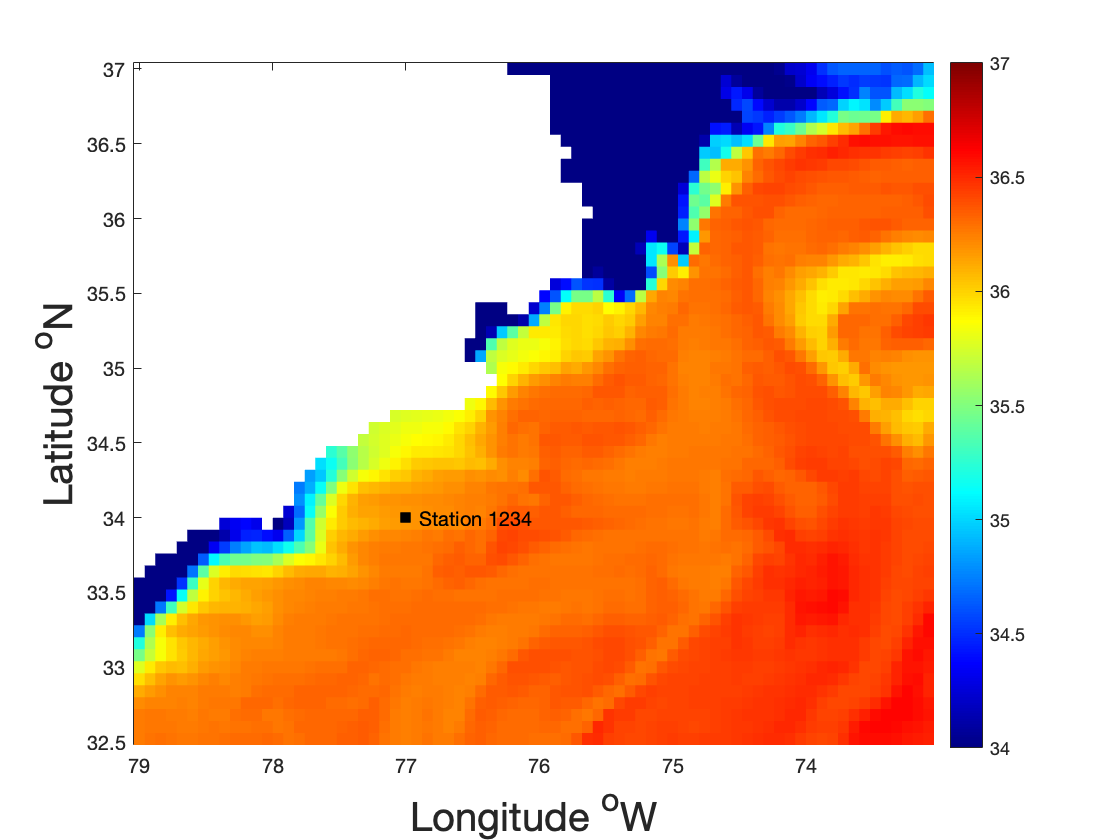

[lon,lat]=meshgrid(lon,lat);
pcolor(lon',lat',squeeze(salt(:,:,1)))
shading flat
colorbar
colormap(jet)
caxis([34 37])
set(gca, 'xtick', [-79:1:-73], 'xticklabel', num2str([79:-1:73]'))
xlabel('Longitude ^oW', 'FontSize',20)
ylabel('Latitude ^oN', 'FontSize',20)
hold on
plot(-77, 34, 'sk', 'markerfacecolor', 'k')
text(-76.9, 34, 'Station 1234')
hold off